### **Método das Secantes**


$$x^{k+1} = \frac{x^{k-1}f(x^{k})-x^{k}f(x^{k-1})}{f(x^{k})- f(x^{k-1})$$


Vamos encontrar o zero da função $f(x) = e^{-x}-x$ no intervalo de $[0,1]$utilizando o método das Secantes, com chute inicial $x^{0} = 0$ e $x^{1} = 1$ e erro relativo igual ou menor que $10^{-2}$.

**Graficamente, **

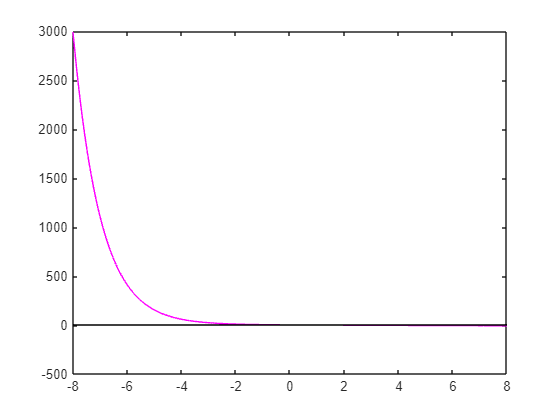

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off

**Implementação das Secantes:**

format long
%Chute inicial
x0 = 0;
x1 = 1;
fx0 = fun(x0);
tol = 10^-2;
k = 0;
er = abs(x1-x0)/abs(x1);
while(er > tol)
    x = (x0*fun(x1)-x1*fun(x0))/(fun(x1)-fun(x0)); %atualizando o zero da função usando o metodo das secantes
    x0 = x1;
    x1 = x;
    er = abs(x1-x0)/abs(x1);%calculando erro relativo
    fx0 = fun(x0);
    k = k+1;
    xk(k,:) = x0;
    fk(k,:) = fun(fx0);
    erk(k,:) = er;
end
[xk,fk, erk]

ans =    1.000000000000000   2.513716946360203   0.632120558828558
   0.612699836780282   1.144195450251198   0.086658603880995
   0.563838389161074   0.989648696217557   0.005874723897691


**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = exp(-x)-x;
end